# BioMDA: Electromagnetic-Kinematic Decoupling Model

## Function: Electromotive Force (EMF) Decoupling Model 

    This function applies a two-step decoupling model to accurately estimate the electromagnetic response from the coil corresponding to a moving implant. Specifically, we constructed the vertical distance decoupling model based on the theoretical electromagnetic interaction between the implants and the sensing unit of BioMDA and the kinematic analysis of the chain reaction triggered by a moving implant (**Fig. 4A**, **Text S1**). 

### Syntax

    output=emf_decoupling(V,D,SF_option)

### Description

    emf=emf_decoupling(V,D, SF_option) returns emf voltages (in mV) with velocity V (in meters per second) and displacement D (in meters) with the option whether to apply the scaling function (true or false).

## Example

    Modeling the response of the sensing unit in BioMDA when an implant approached the sensor from 15mm to a minimum distance of 2 - 6.5 mm with varying constant speed from 7.5 to 15 mm/s with an incrementation of 0.5 mm in both distance and velocity, and compareing with 1525 test samples when the implant was controlled by a Micro-Newton tester (Instron, 5942) (**Fig. 4E)**.

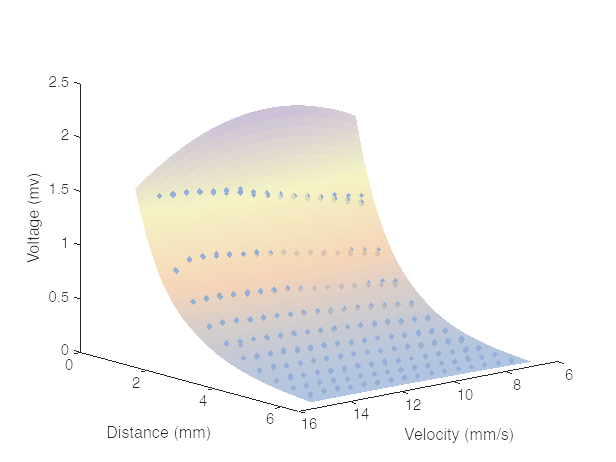

load Colormap.mat
v=7:0.05:15.5;
d=1.25:0.05:6.5;
[V,D] = meshgrid(v/1000,d/1000);
SF_option=true; % with Scaling Function
emf_sf=emf_decoupling(V,D,SF_option);
figure(1)
hold on
surf(V*1000,D*1000,emf_sf,'EdgeColor','none','FaceAlpha',0.75);
colormap(CustomColormap) %apply custom colormap
test_samples=readmatrix('fig4_data.xls','sheet',1);
custom_color=[0.58,0.69,0.84];%appy custom color
scatter3(test_samples(:,1),test_samples(:,2),test_samples(:,3),9,custom_color,"filled");
xlabel('Velocity (mm/s)')
ylabel('Distance (mm)')
zlabel('Voltage (mv)')
view(140,16)
zlim([0 2.5])
xlim([6 16])
ylim([0 6.5])

## Example

    Visualize of the difference between the theoretical emf model without and with the calibrated attenuation model. The calibration approximates the scaling between theoretical model  to the captured inducing signal across the coil and can be divided into two steps scaling in the distance space and velocity space (**Fig. 4B, C and D).**

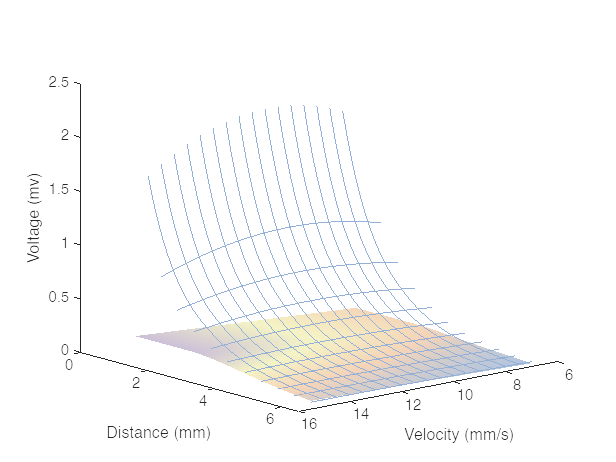

v=7:0.05:15.5;
x=1.25:0.05:6.5;
[V,X] = meshgrid(v/1000,x/1000);
SF_option=true; % with Scaling Function
emf_sf=emf_decoupling(V,X,SF_option);
SF_option=false; % with Scaling Function
emf=emf_decoupling(V,X,SF_option);
figure(2)
hold on
s=surf(V*1000,X*1000,emf,'EdgeColor','none','FaceAlpha',0.75);
colormap(CustomColormap) %apply custom colormap
for exp_v=7.5:0.5:15
    idx=V*1000==exp_v;
    plot3(V(idx)*1000,X(idx)*1000,emf_sf(idx),'color',custom_color);
end

for exp_x=2:0.5:6.5
    idx=X*1000==exp_x;
    plot3(V(idx)*1000,X(idx)*1000,emf_sf(idx),'color',custom_color);
end
xlabel('Velocity (mm/s)')
ylabel('Distance (mm)')
zlabel('Voltage (mv)')
view(140,16)

To visualize two steps scaling function in the distance space and velocity space:

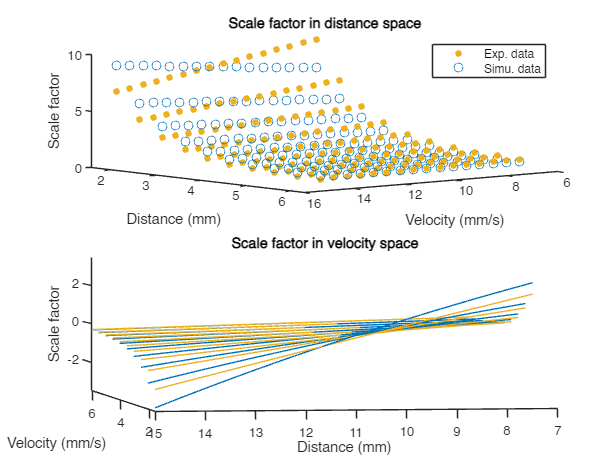

% scaling parameters learned through regression
P=[0.2170  -11.8572];
x2_d=[3.794558e+01,1.104246e+00];
x2_k=[-4.338194e+00,-5.936298e-02];
test_scales=readmatrix('fig4_data.xls','sheet',2);
v=test_scales(:,1);d=test_scales(:,2);sf=test_scales(:,3);
sf_d=(x2_d(1)*exp(-d)+x2_d(2));
custom_color1=[0 0.45 0.74];
custom_color2=[0.93 0.69 0.12];
figure(3)
subplot(2,1,1)
hold on
title('Scale factor in distance space')
p1=plot3(v,d,sf,'o','MarkerFaceColor',custom_color2,'MarkerEdgeColor',custom_color2,'MarkerSize',4);
p2=plot3(v,d,sf_d,'o','Color',custom_color1,'MarkerSize',6);
xlabel('Velocity (mm/s)')
ylabel('Distance (mm)')
zlabel('Scale factor')
view(140,16)
legend([p1 p2],'Exp. data','Simu. data','Location','northeast')
%%
subplot(2,1,2)
hold on
title("Scale factor in velocity space")
delta_v=sf-sf_d;  
sf_k=(x2_k(1)*exp(-d)+x2_k(2)).*(v+P(1)*d+P(2));
d_10=1.58:0.5:6.28;
for j = 1:10
    i=j:10:length(delta_v);
    plot3(zeros(size(i))+d_10(j),v(i),delta_v(i),'-','Color',custom_color2) 
    plot3(zeros(size(i))+d_10(j),v(i),sf_k(i),'-','Color',custom_color1) 
end
xlabel('Velocity (mm/s)')
ylabel('Distance (mm)')
zlabel('Scale factor')
view(-99,9)
zlim([-3.5 3.5])

For citation: 